## Mesh processing toolbox

### Author & support : nicolas.douillet (at) free.fr, 2020.

### Example #1 : vertex normals

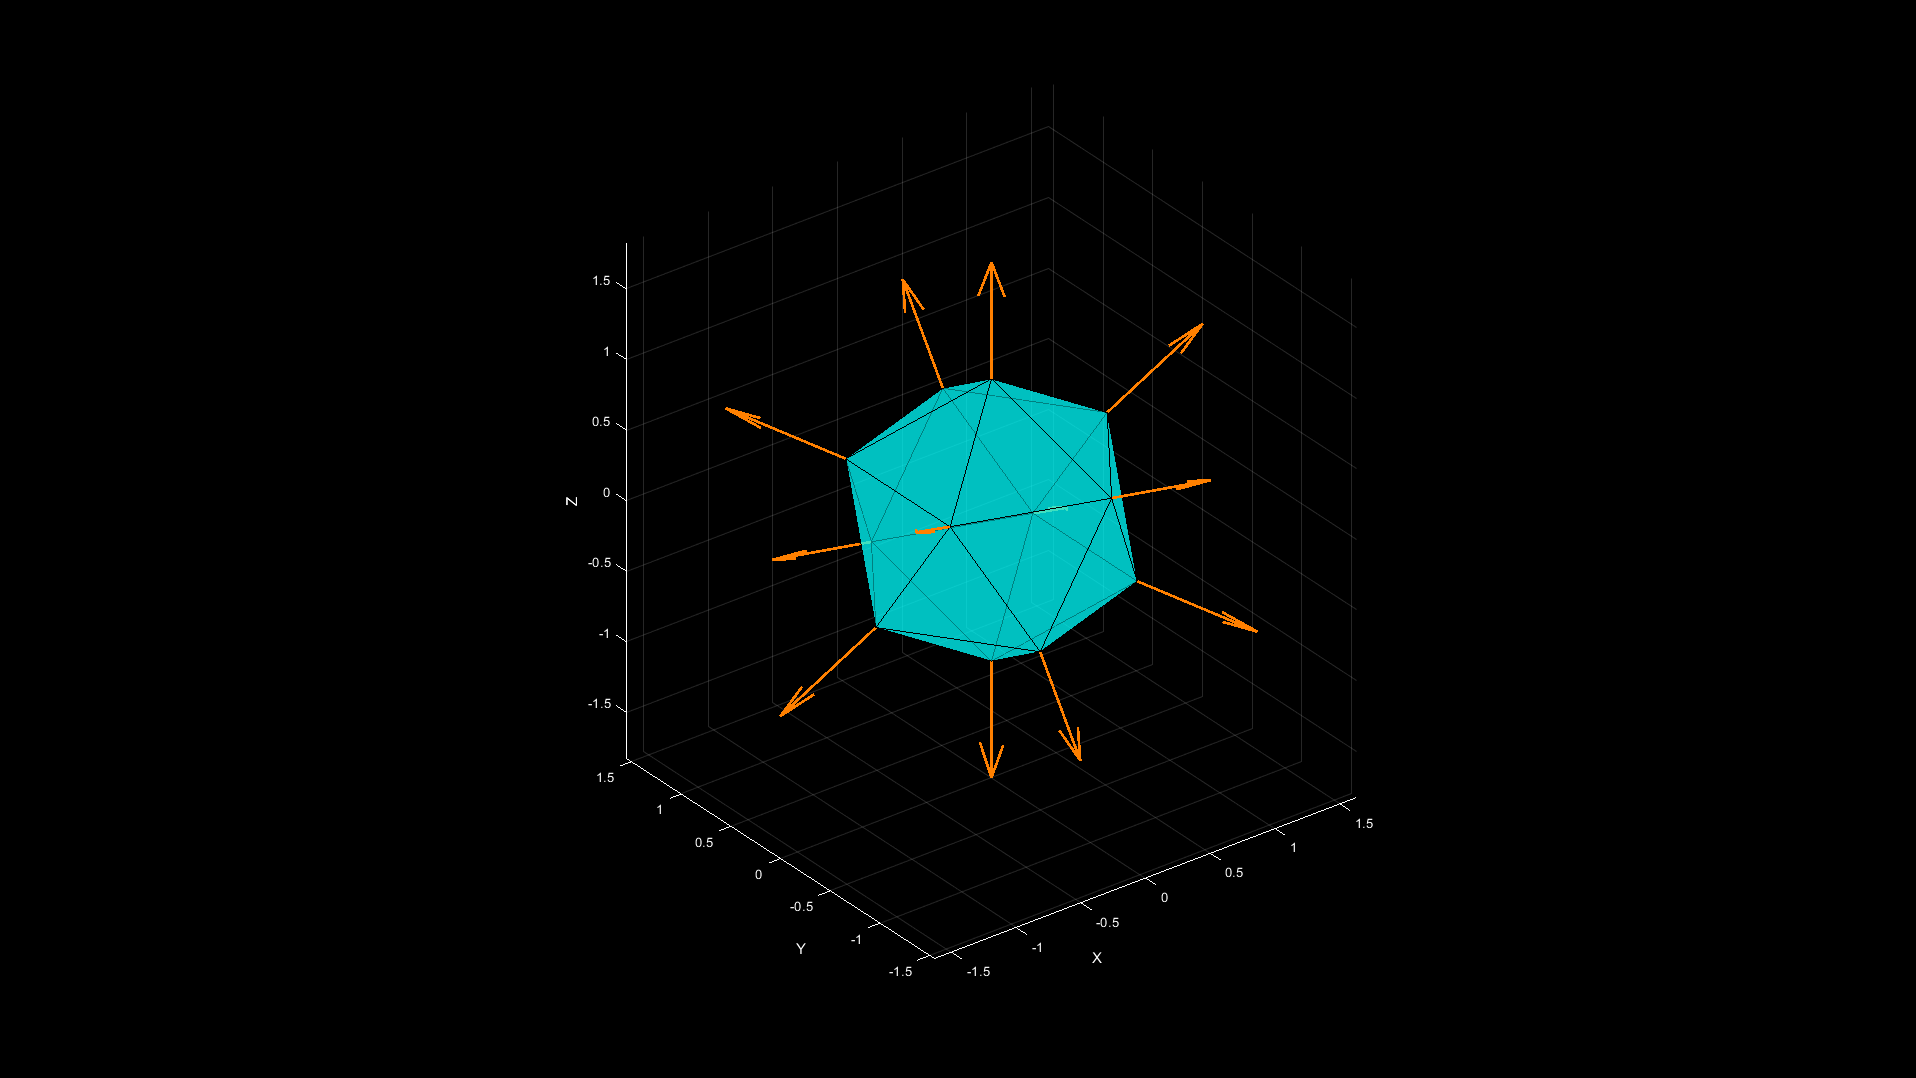

Mesh with 12 vertices and 20 triangles displayed in 2.620721e-01 seconds.


addpath('data/');
addpath('src/');

load('icosahedron.mat');
ngb_degre = 1;
select_vertex_normals(V,T,ngb_degre);

### Example #2 : non manifold triangles

load('kitten_nmnfld.mat');
nmnfld_tgl_idx_list = select_non_manifold_triangles(V,T);

Mesh with 5224 vertices and 10911 triangles displayed in 1.166928e-01 seconds.


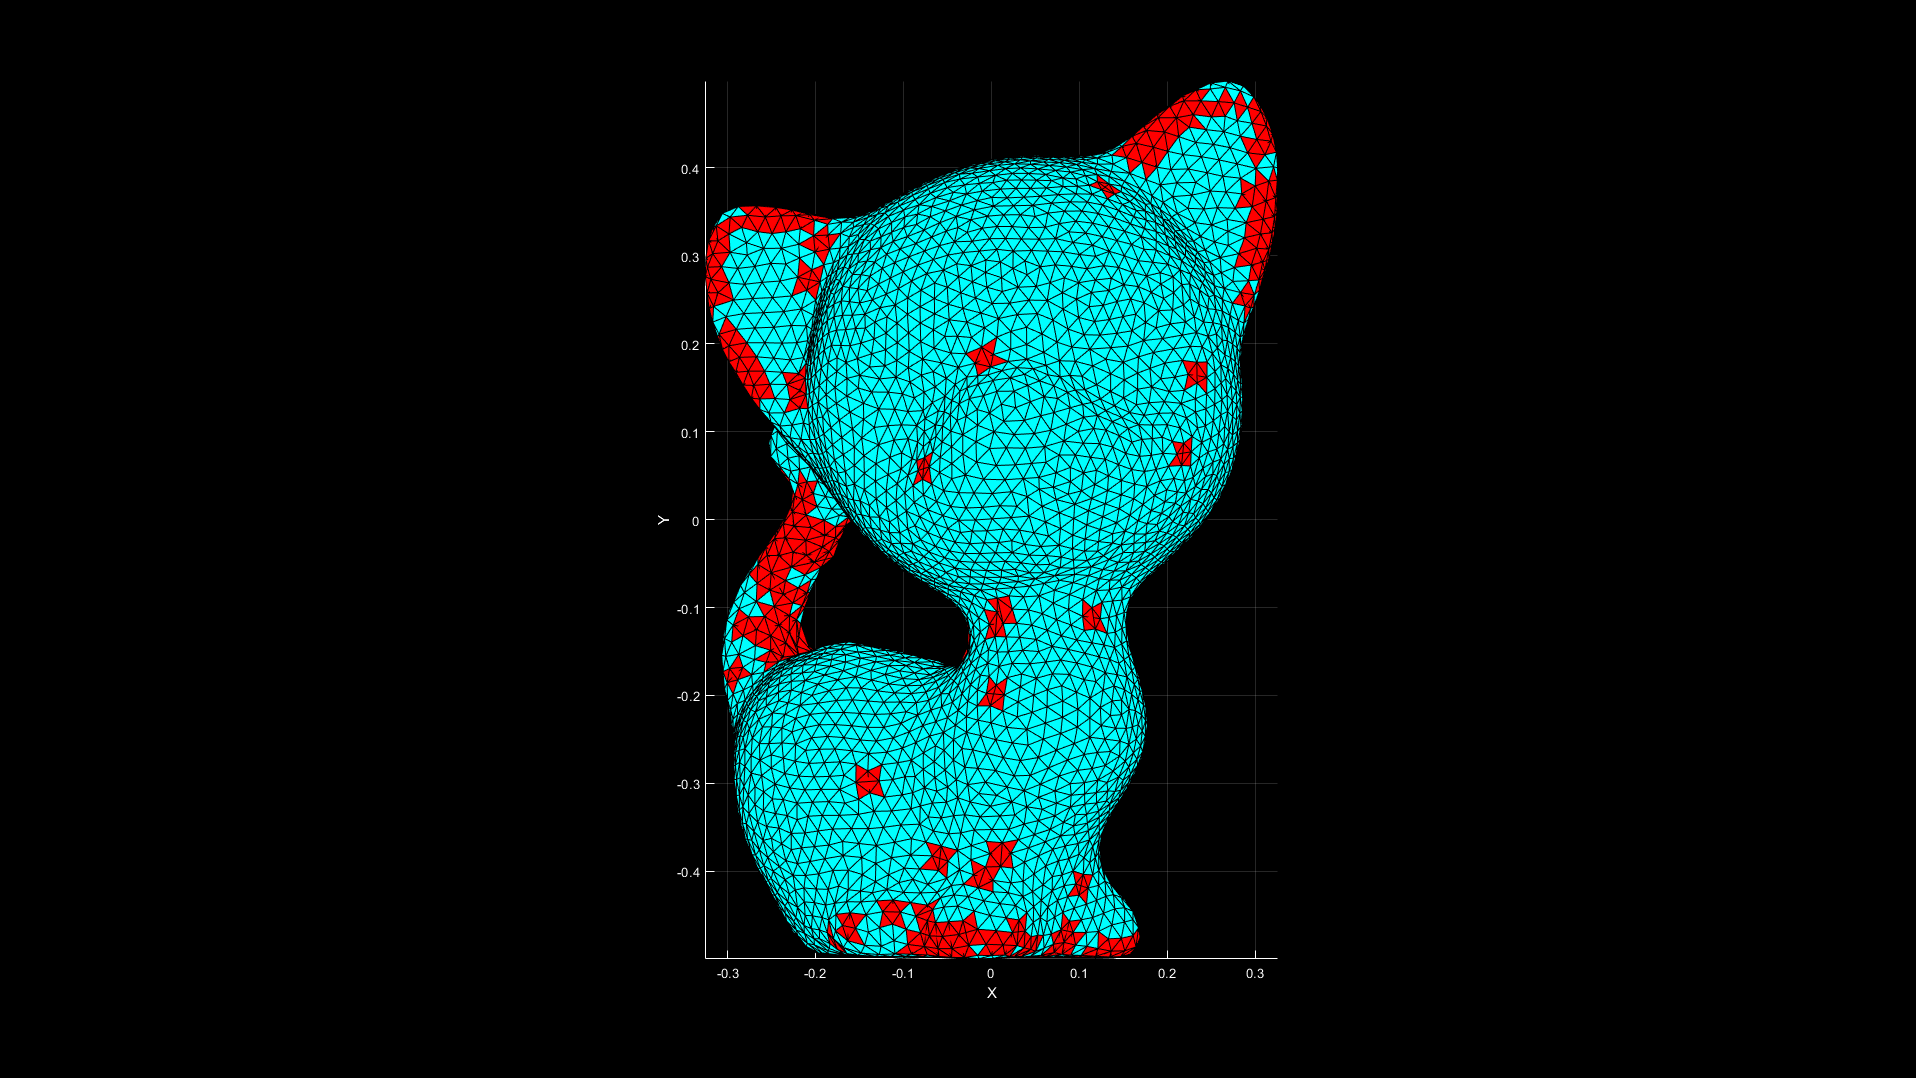

view(0,90);

### Example #3 : connected components

load('kitten_components.mat');
[cc_nb,components] = segment_connected_components(T);

4 components found in 1.433567e+00 seconds.


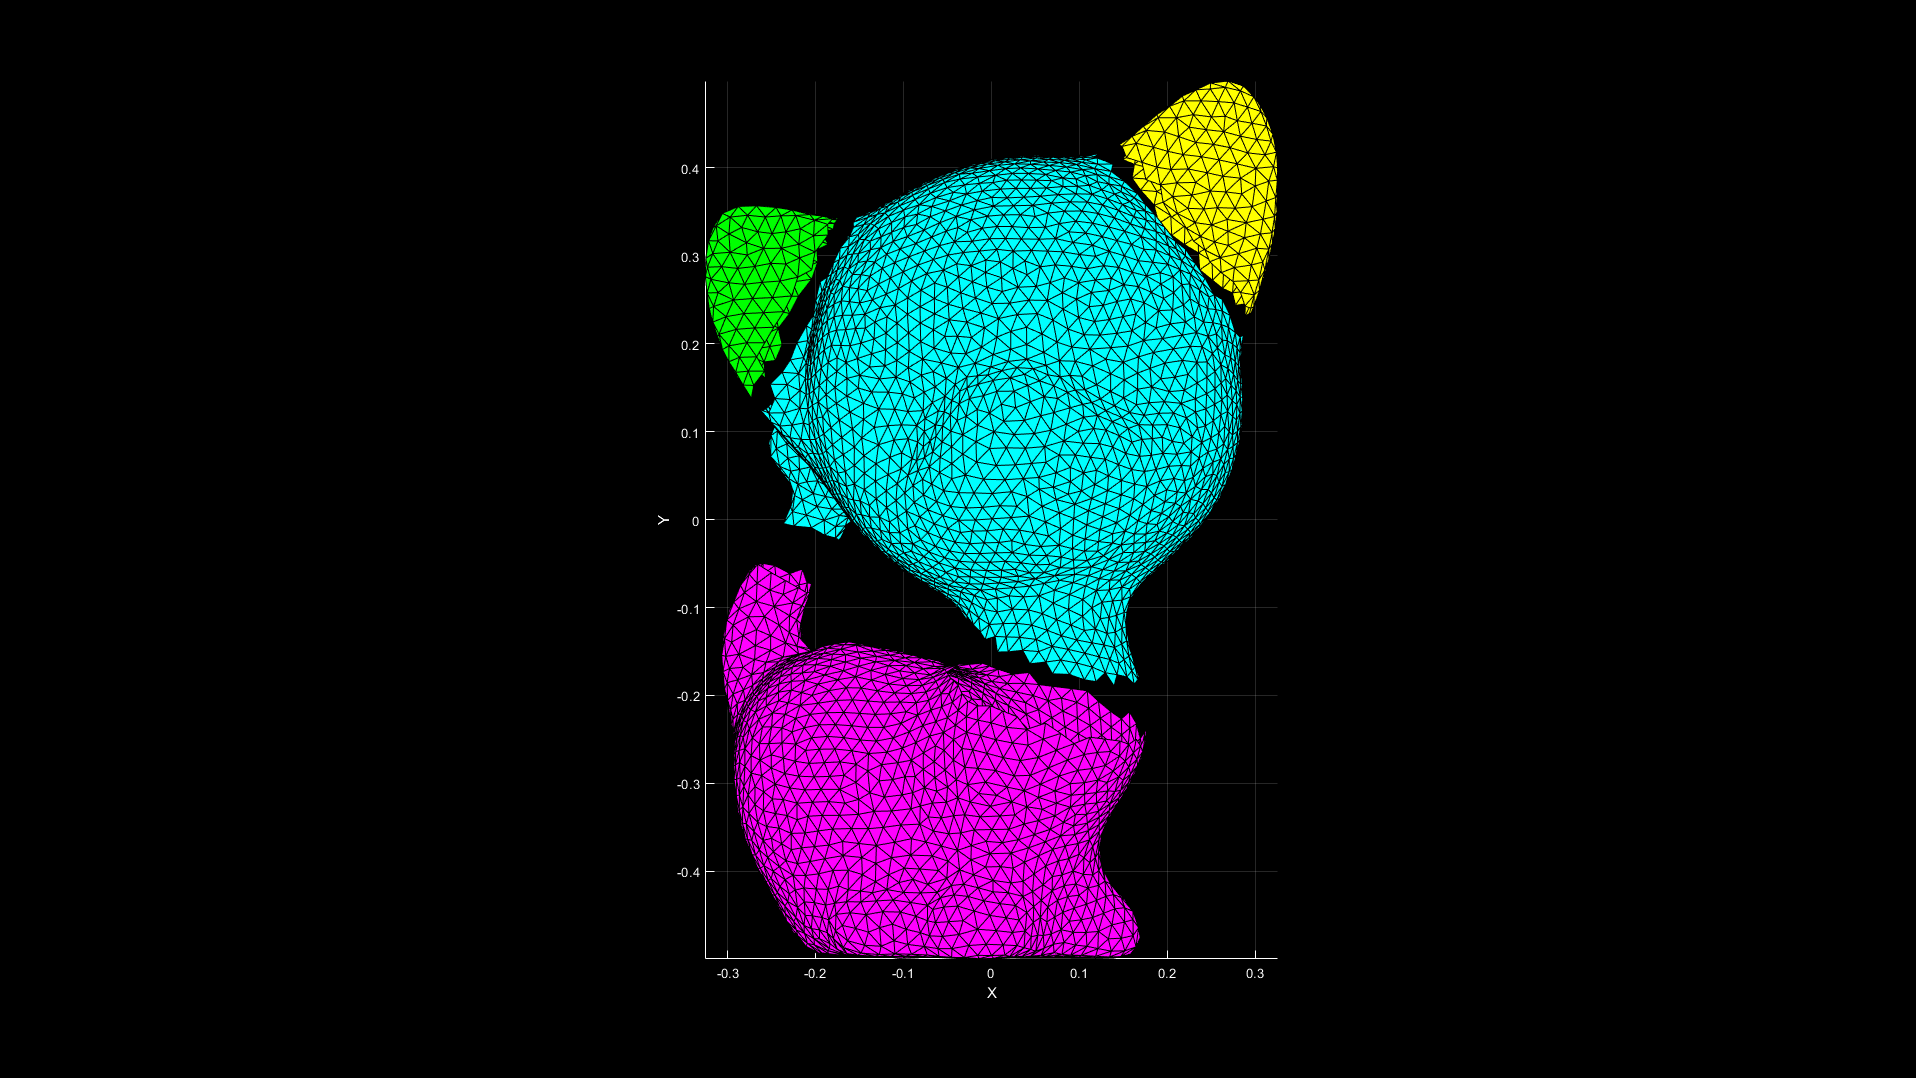

show_mesh_components(V,components);
view(0,90);

### Example #4 : holes and boundary selection

load('kitten_holed.mat');
nmnfld_vtx_idx = select_non_manifold_vertices(V,T,false);
[V,T] = clone_solve_nmnfld_vertices(V,T,nmnfld_vtx_idx);

1 components found in 5.844900e-03 seconds.
1 components found in 7.748000e-04 seconds.
1 components found in 9.704000e-04 seconds.
1 components found in 6.509800e-03 seconds.
2 components found in 4.360600e-03 seconds.
duplicate_nmnfld_vertices request executed in 5.747690e-02 seconds. 5 clone vertices added.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 6.819390e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 7.578710e-02 seconds.


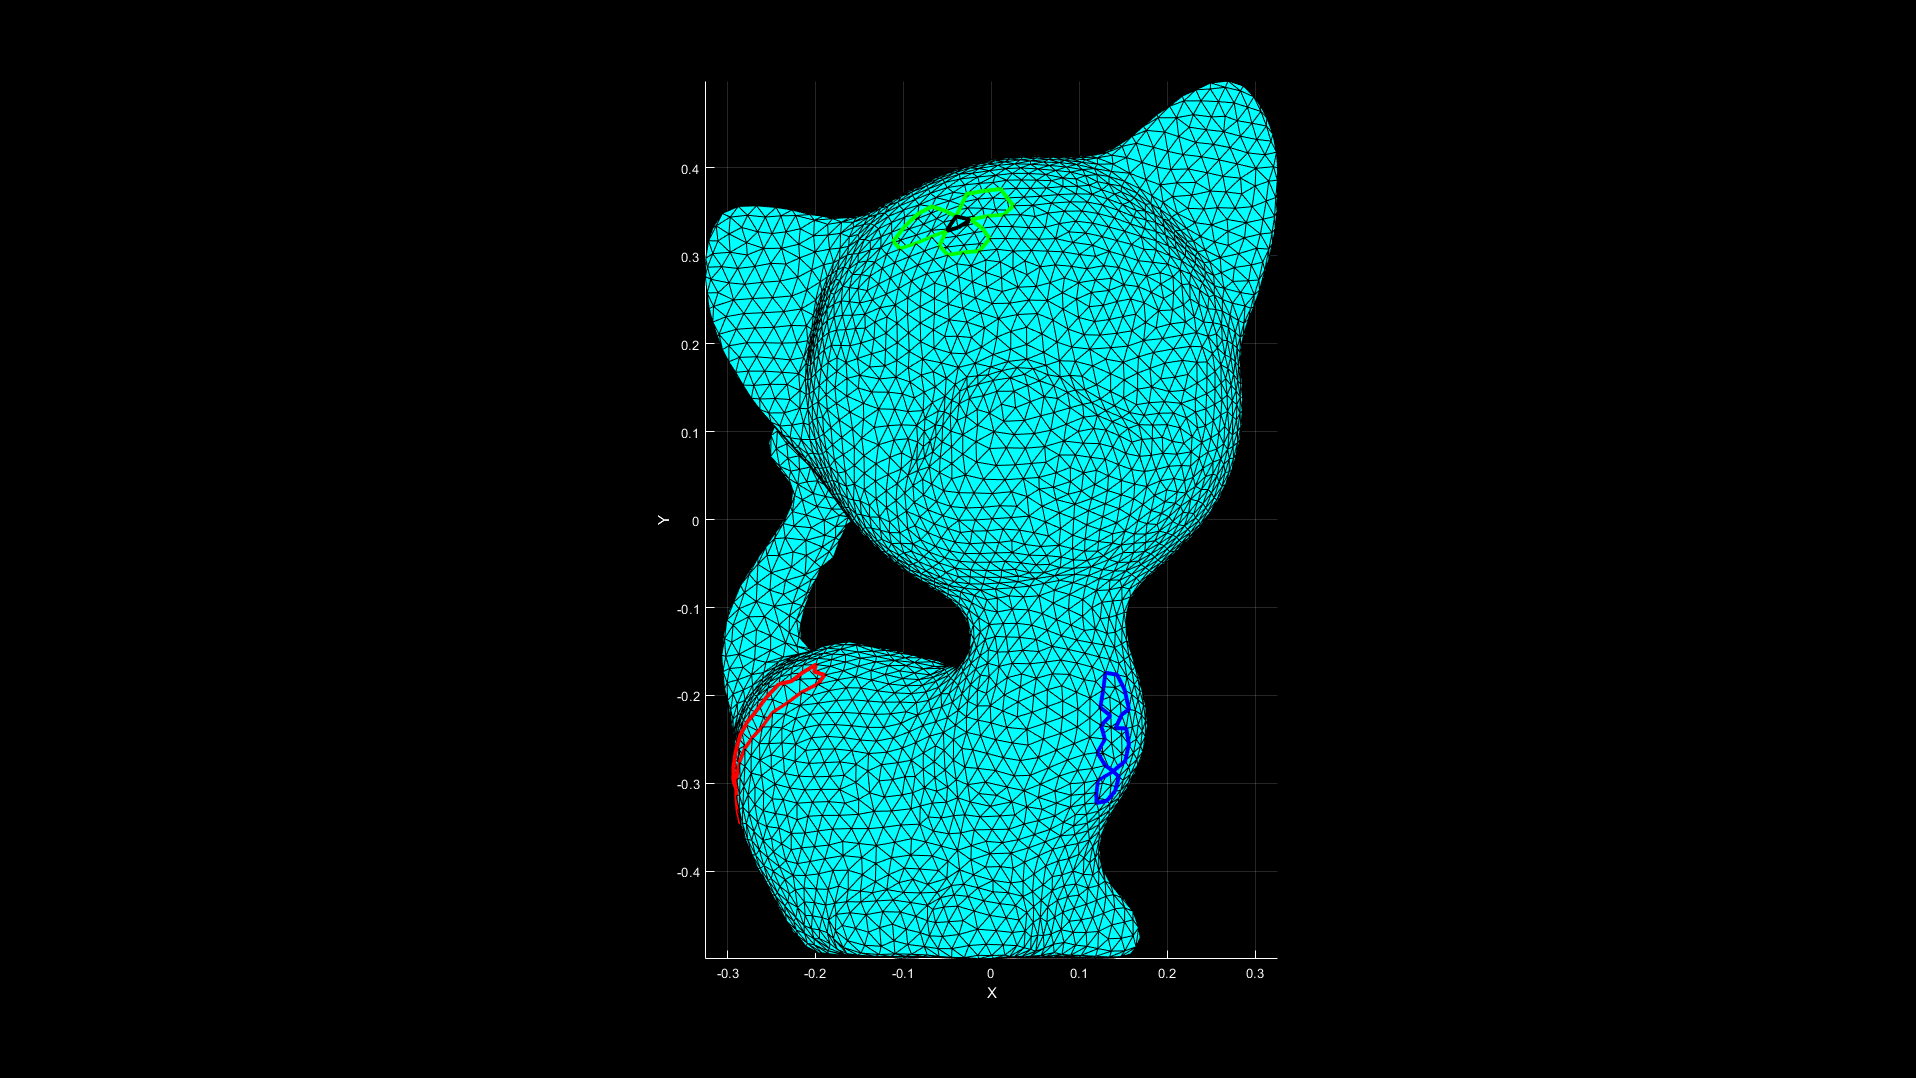

view(0,90);

### Example #5 : hole filling

[V,T] = remove_non_manifold_vertices(V,T);

0 non manifold vertices removed in 8.031889e-01 seconds.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 6.559180e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 9.761730e-02 seconds.


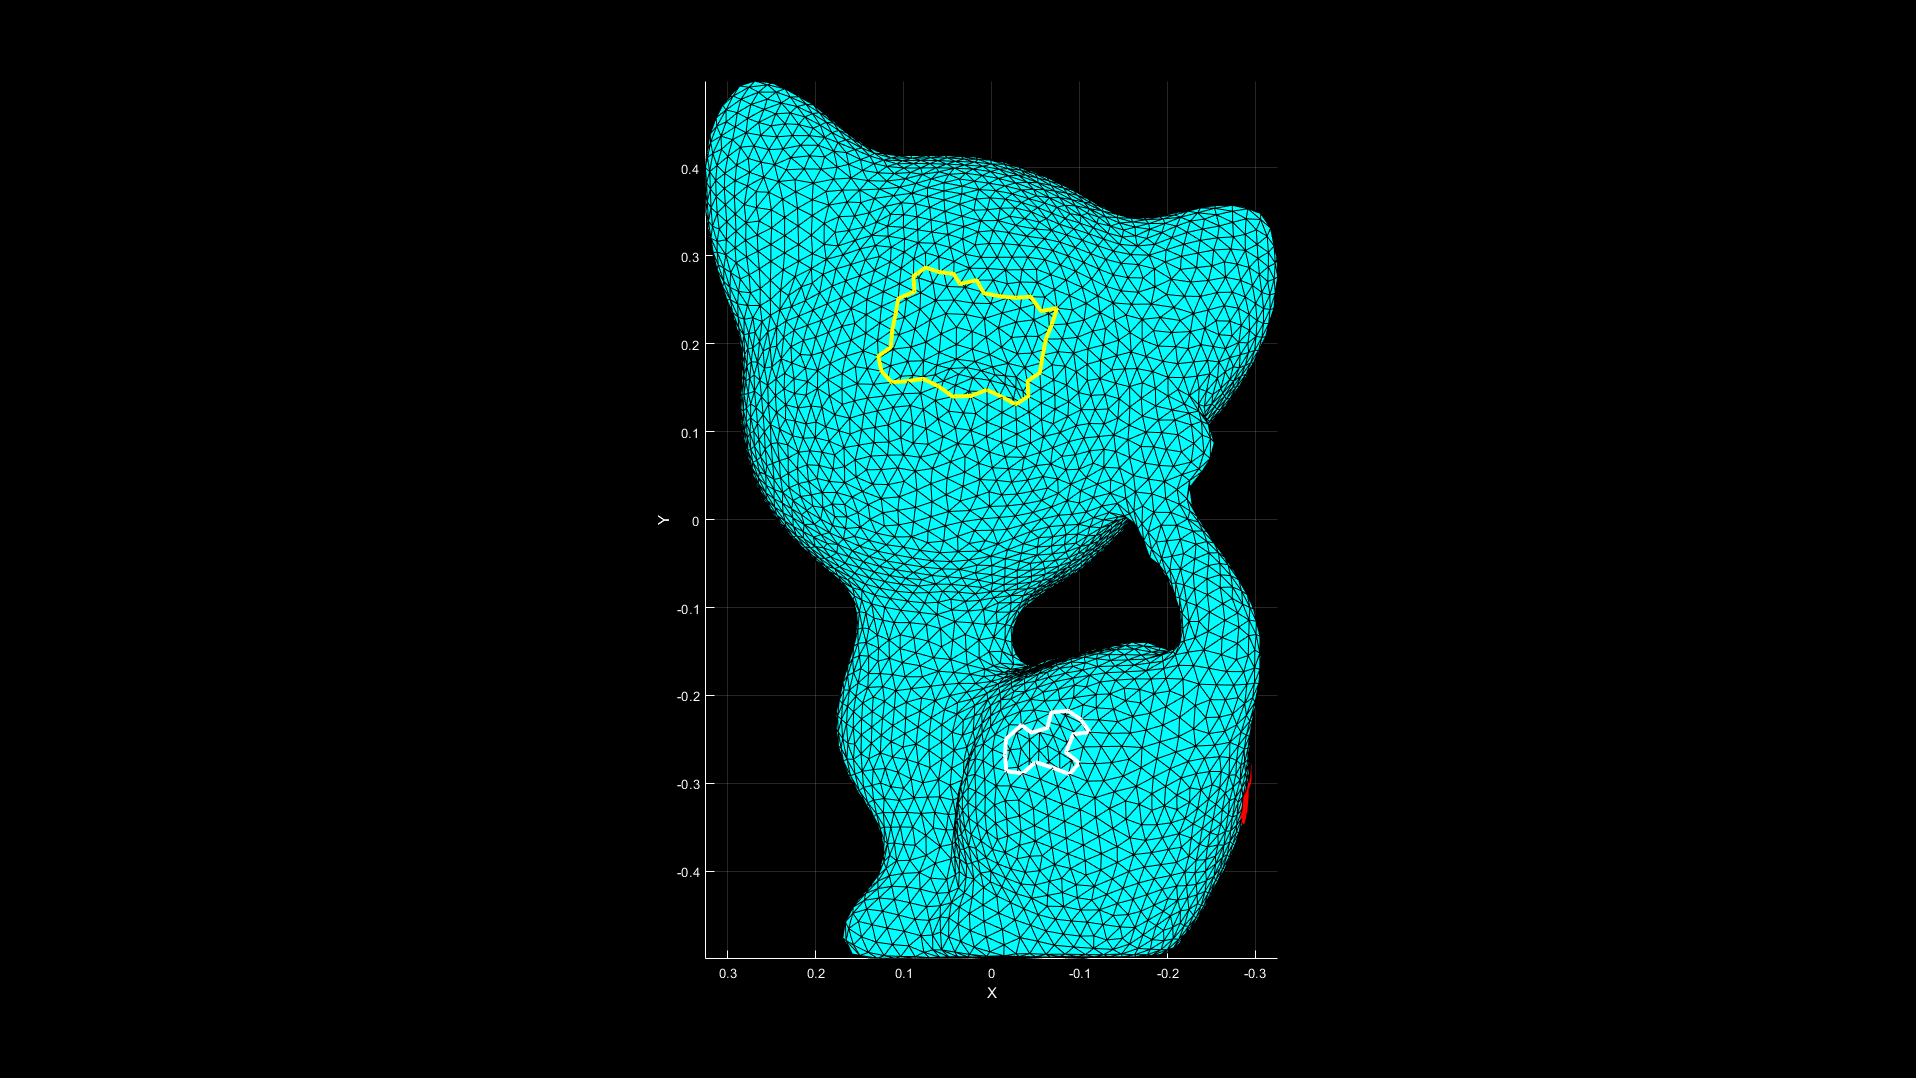

view(-180,-90);


max_perim_sz = 200;
T = fill_mesh_holes(V,T,boundaries,'closed',max_perim_sz);

6 hole(s) filled by adding 121 triangles in 5.391945e-01 seconds.


plot_mesh(V,T);

Mesh with 5120 vertices and 10236 triangles displayed in 7.064830e-02 seconds.


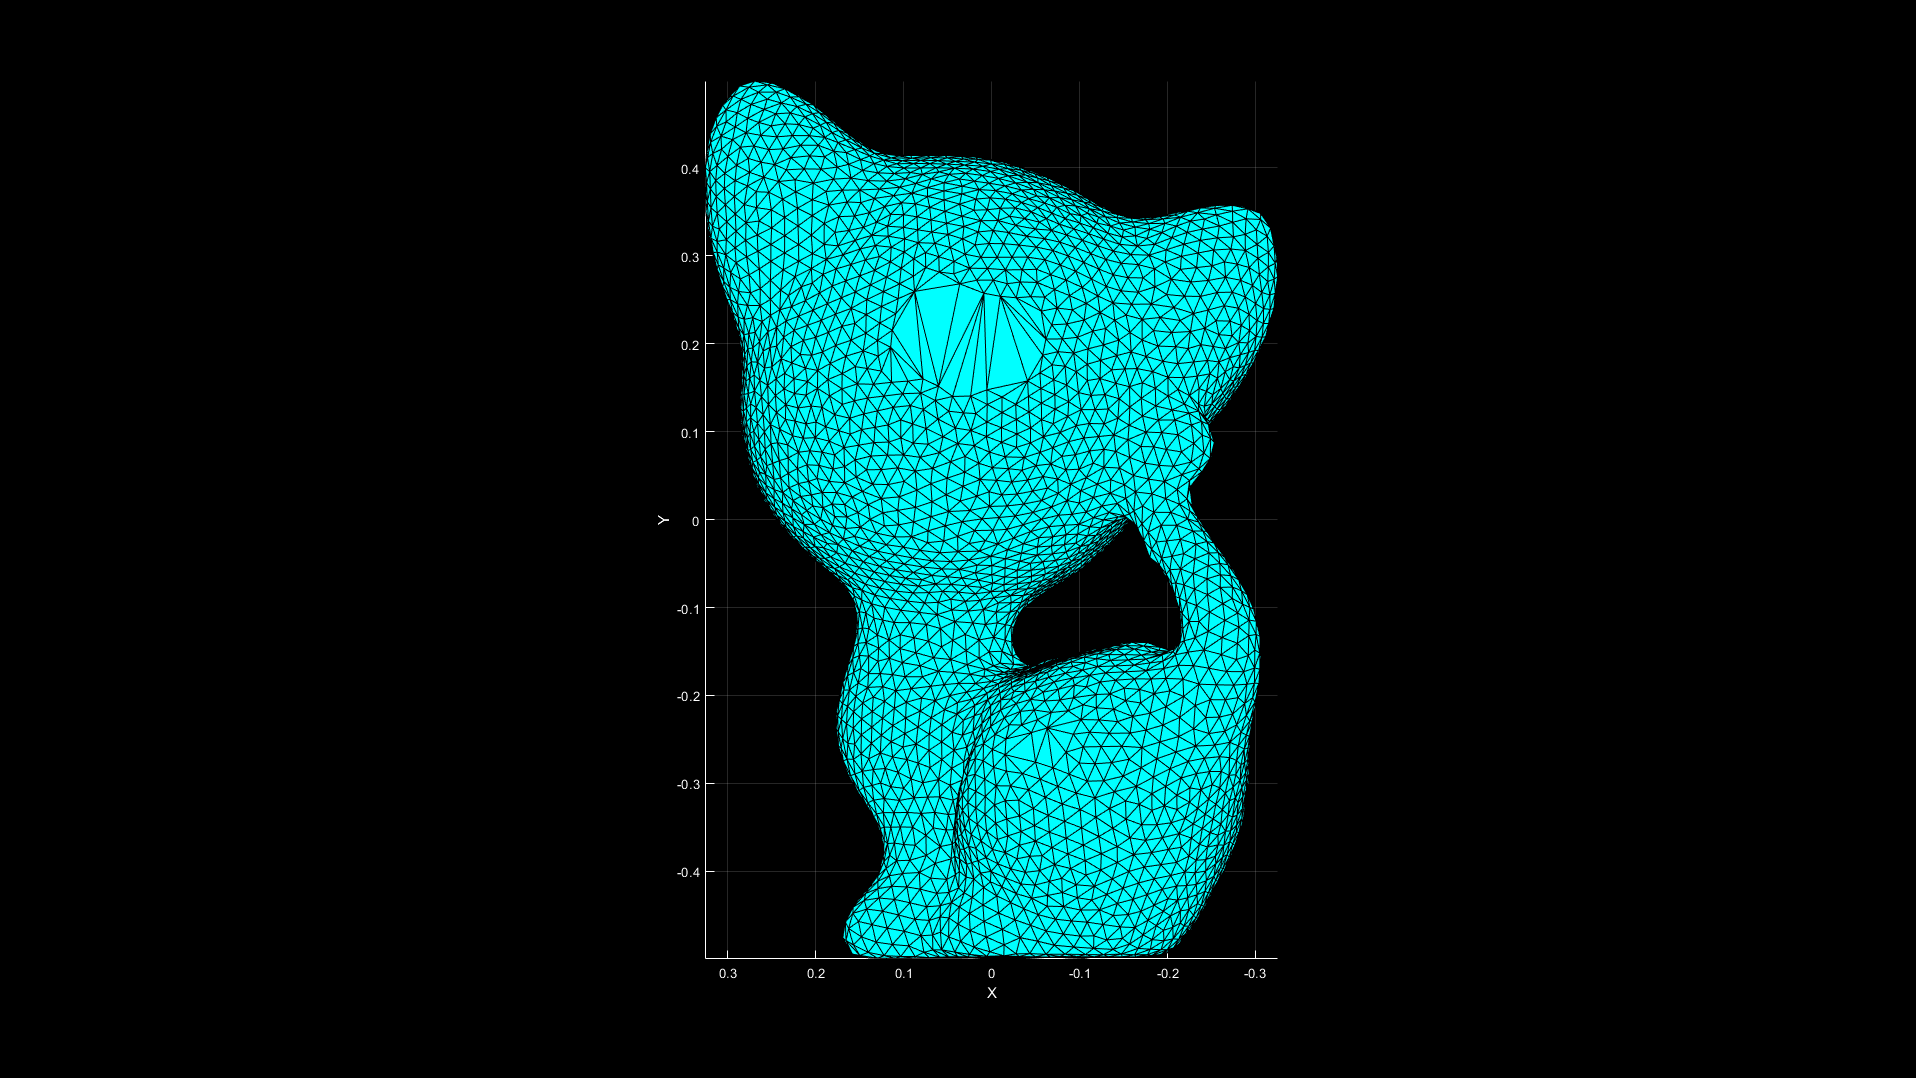

view(-180,-90);

### Example #6 : curvature

load('kitten.mat');
ngb_degre = 2;
N = compute_vertex_normals(V,T,ngb_degre,'raw');
curvature = compute_mesh_curvature(V,T,N,ngb_degre,'mean');

mean curvature computed in 6.594934e-01 seconds.


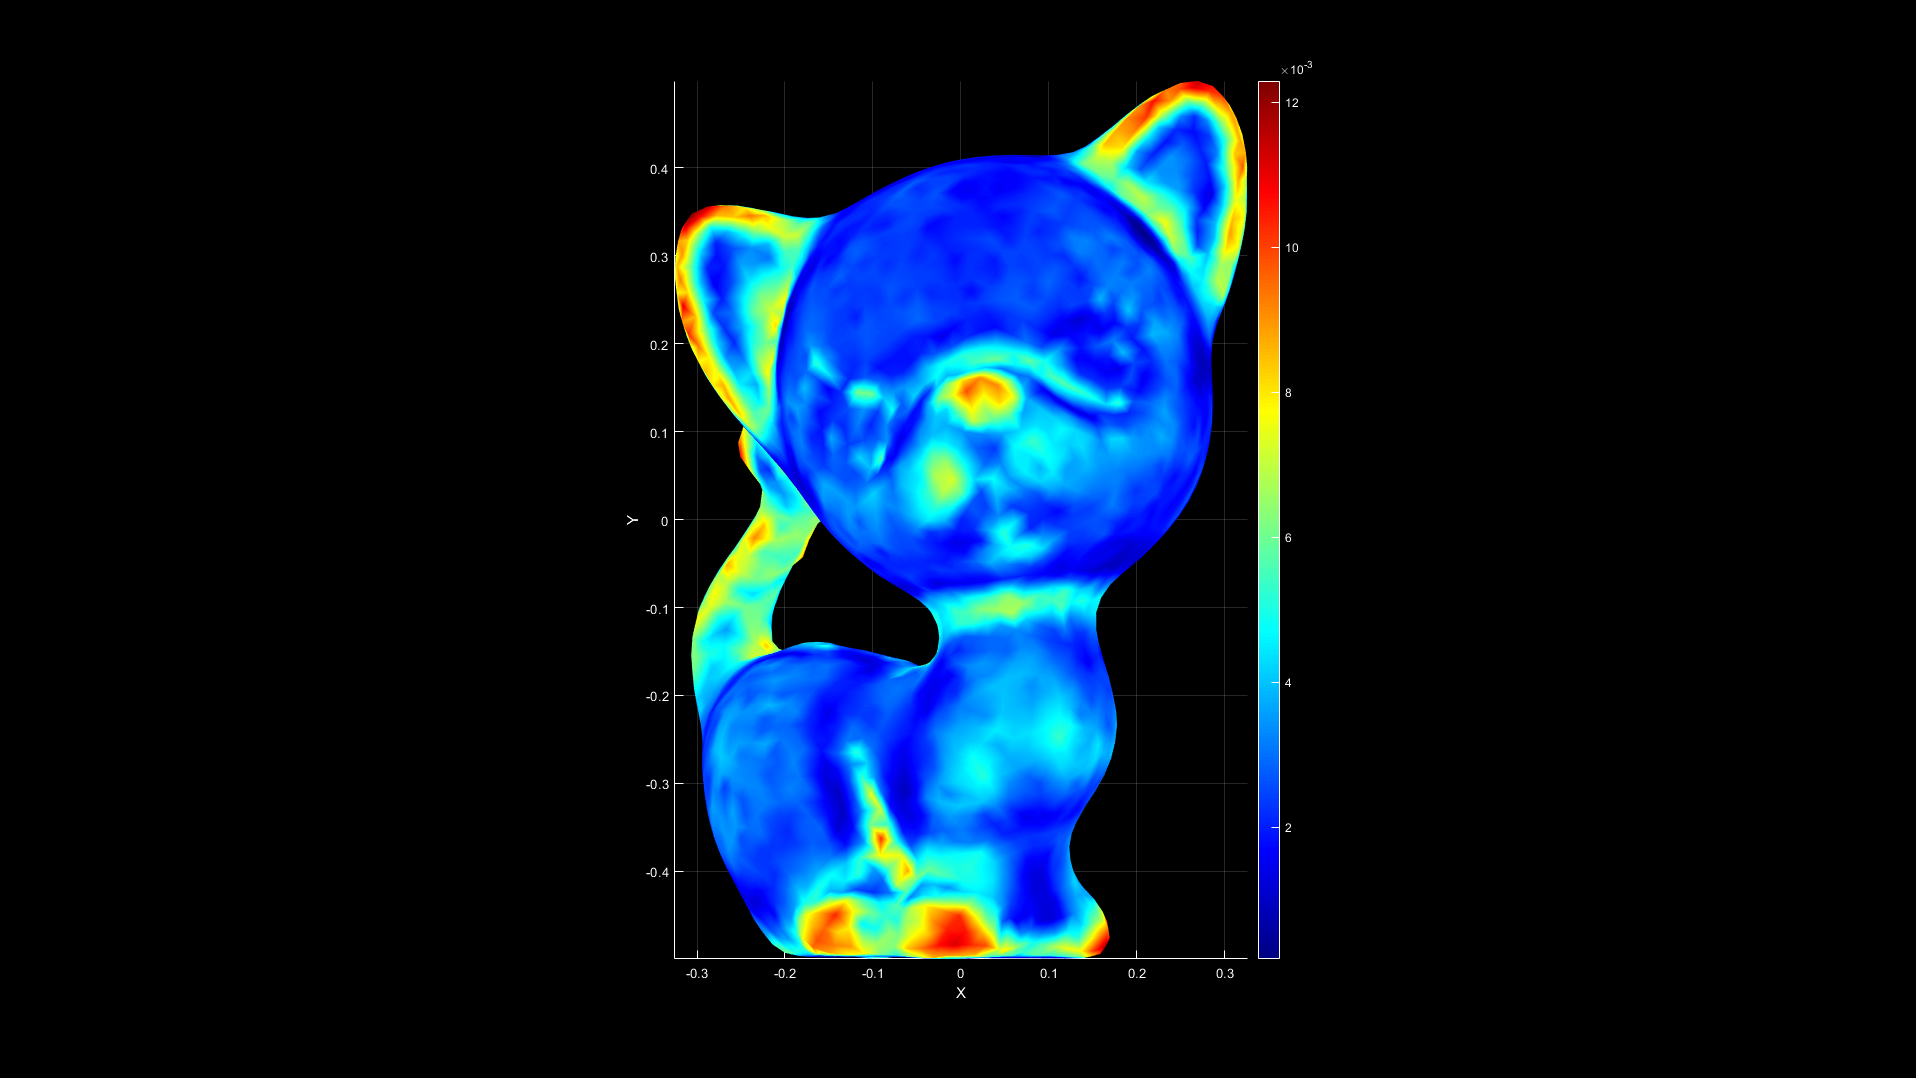

show_mesh_curvature(V,T,curvature);
view(0,90);

### Example #7 : subselection

load('Gargoyle_3k.mat');
plot_mesh(V,T);

Mesh with 1429 vertices and 2836 triangles displayed in 7.508160e-02 seconds.


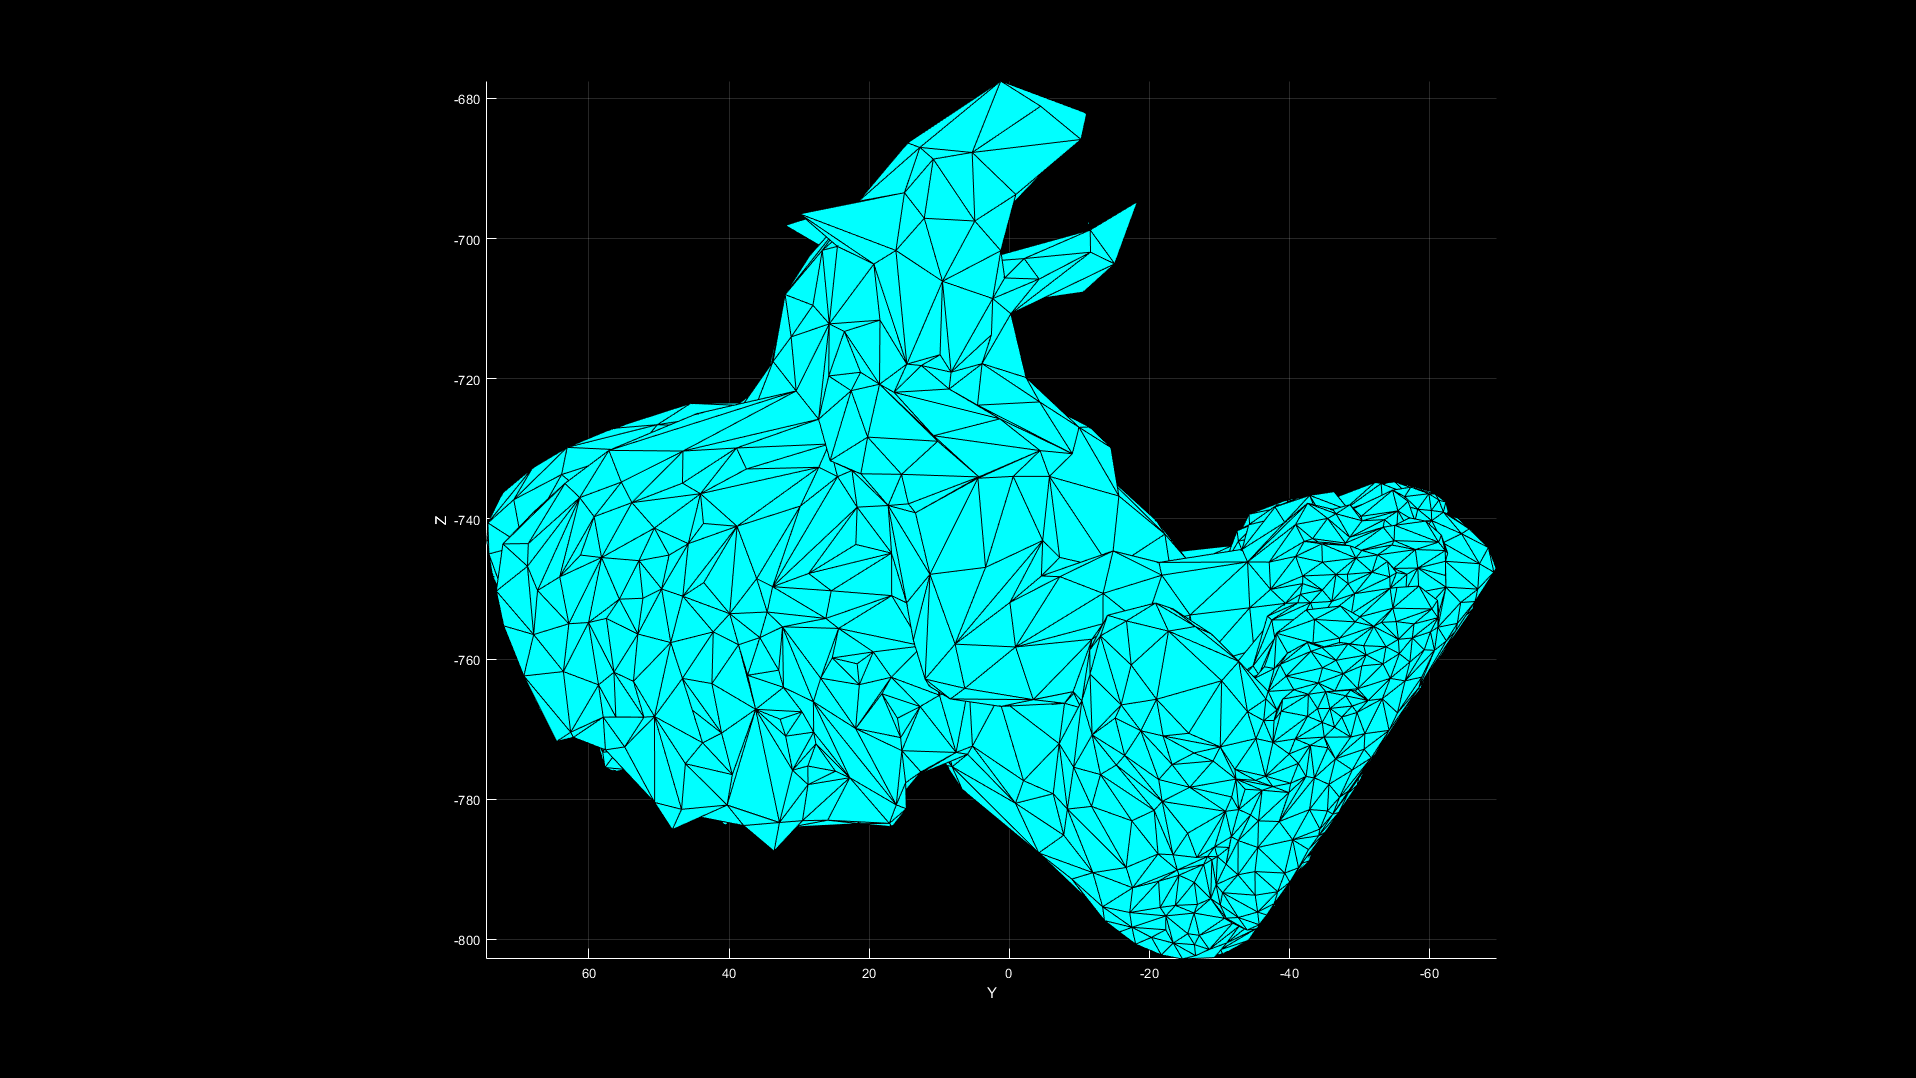

view(-90,0);


n = [0 1 0];
I = [0 -25 800];
[V_out,T_out] = submesh_selection(V,T,n,I); % Gargoyle top part 

submesh with 729 vertices and 4221 triangles selected in 3.222450e-02 seconds.



plot_mesh(V_out,T_out);

Mesh with 726 vertices and 4221 triangles displayed in 6.840620e-02 seconds.


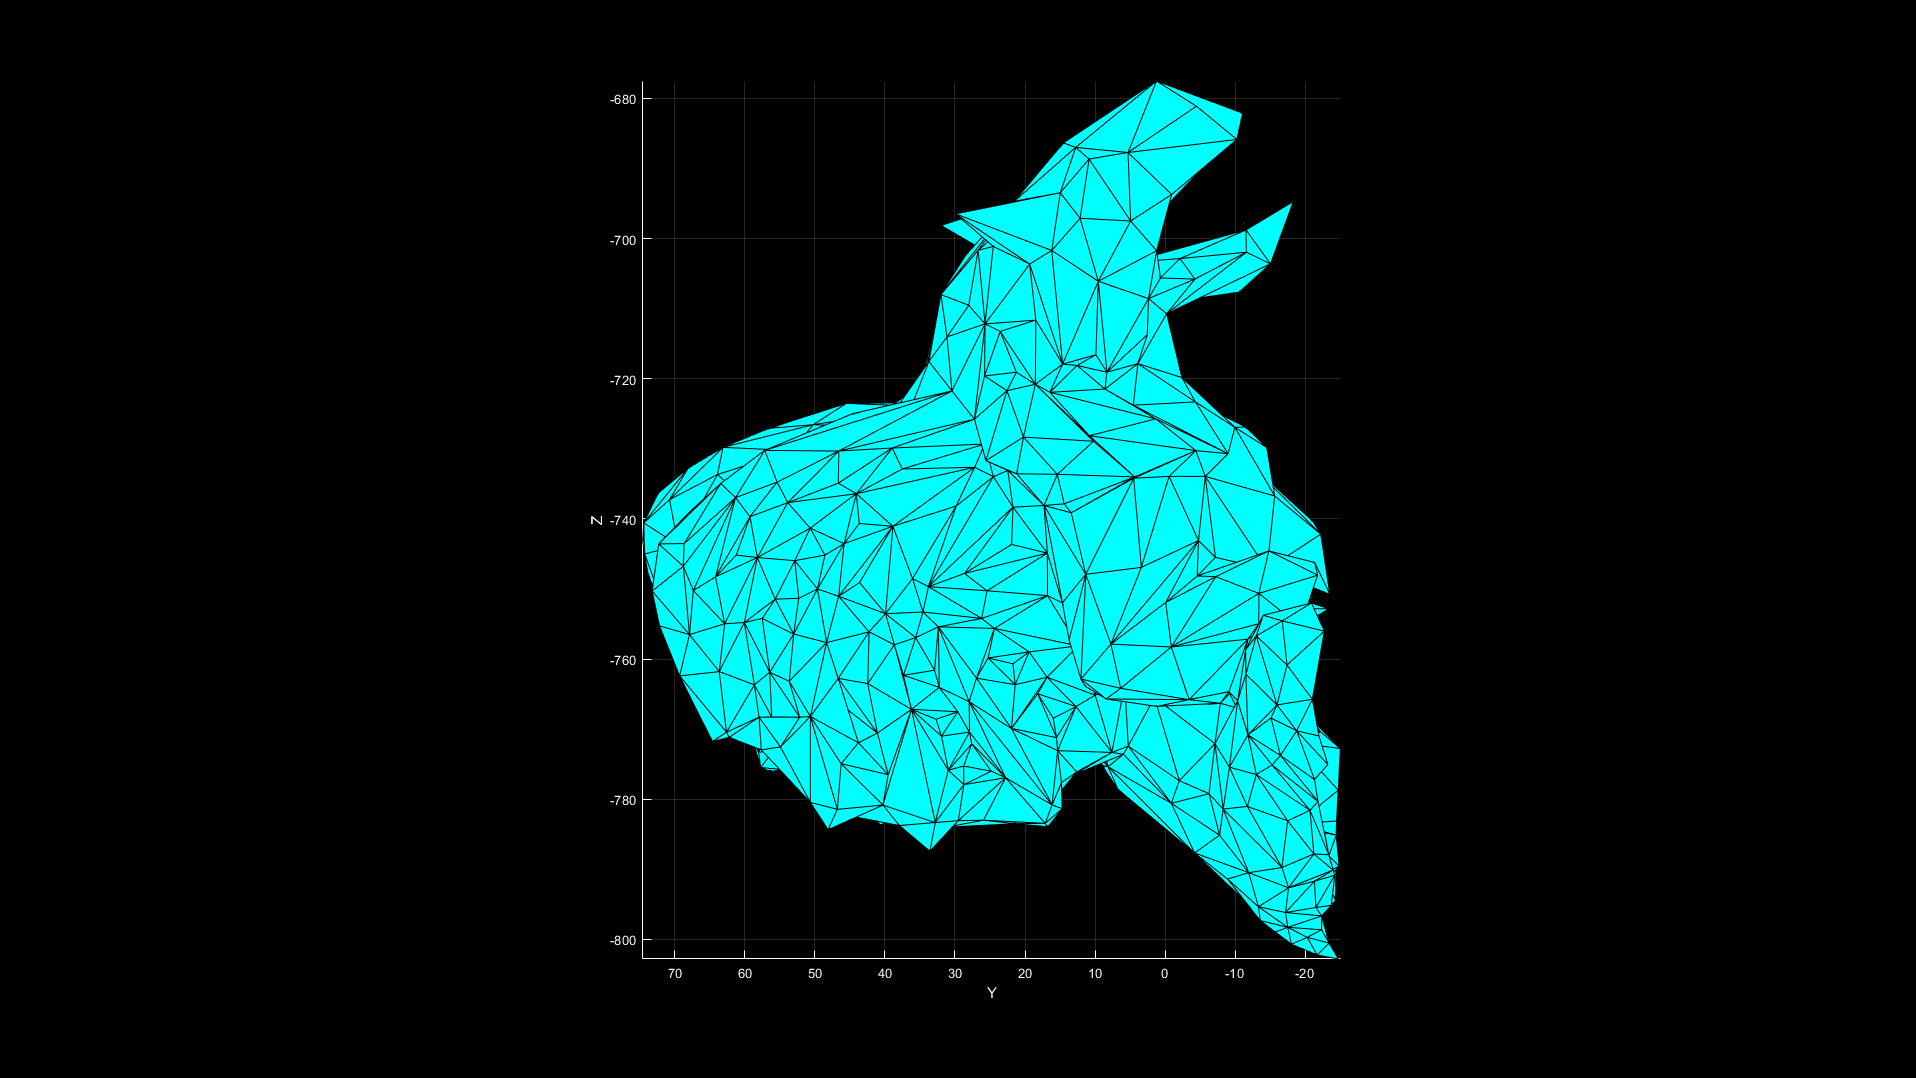

view(-90,0);

### Example #8 : smoothing

plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 6.868670e-02 seconds.


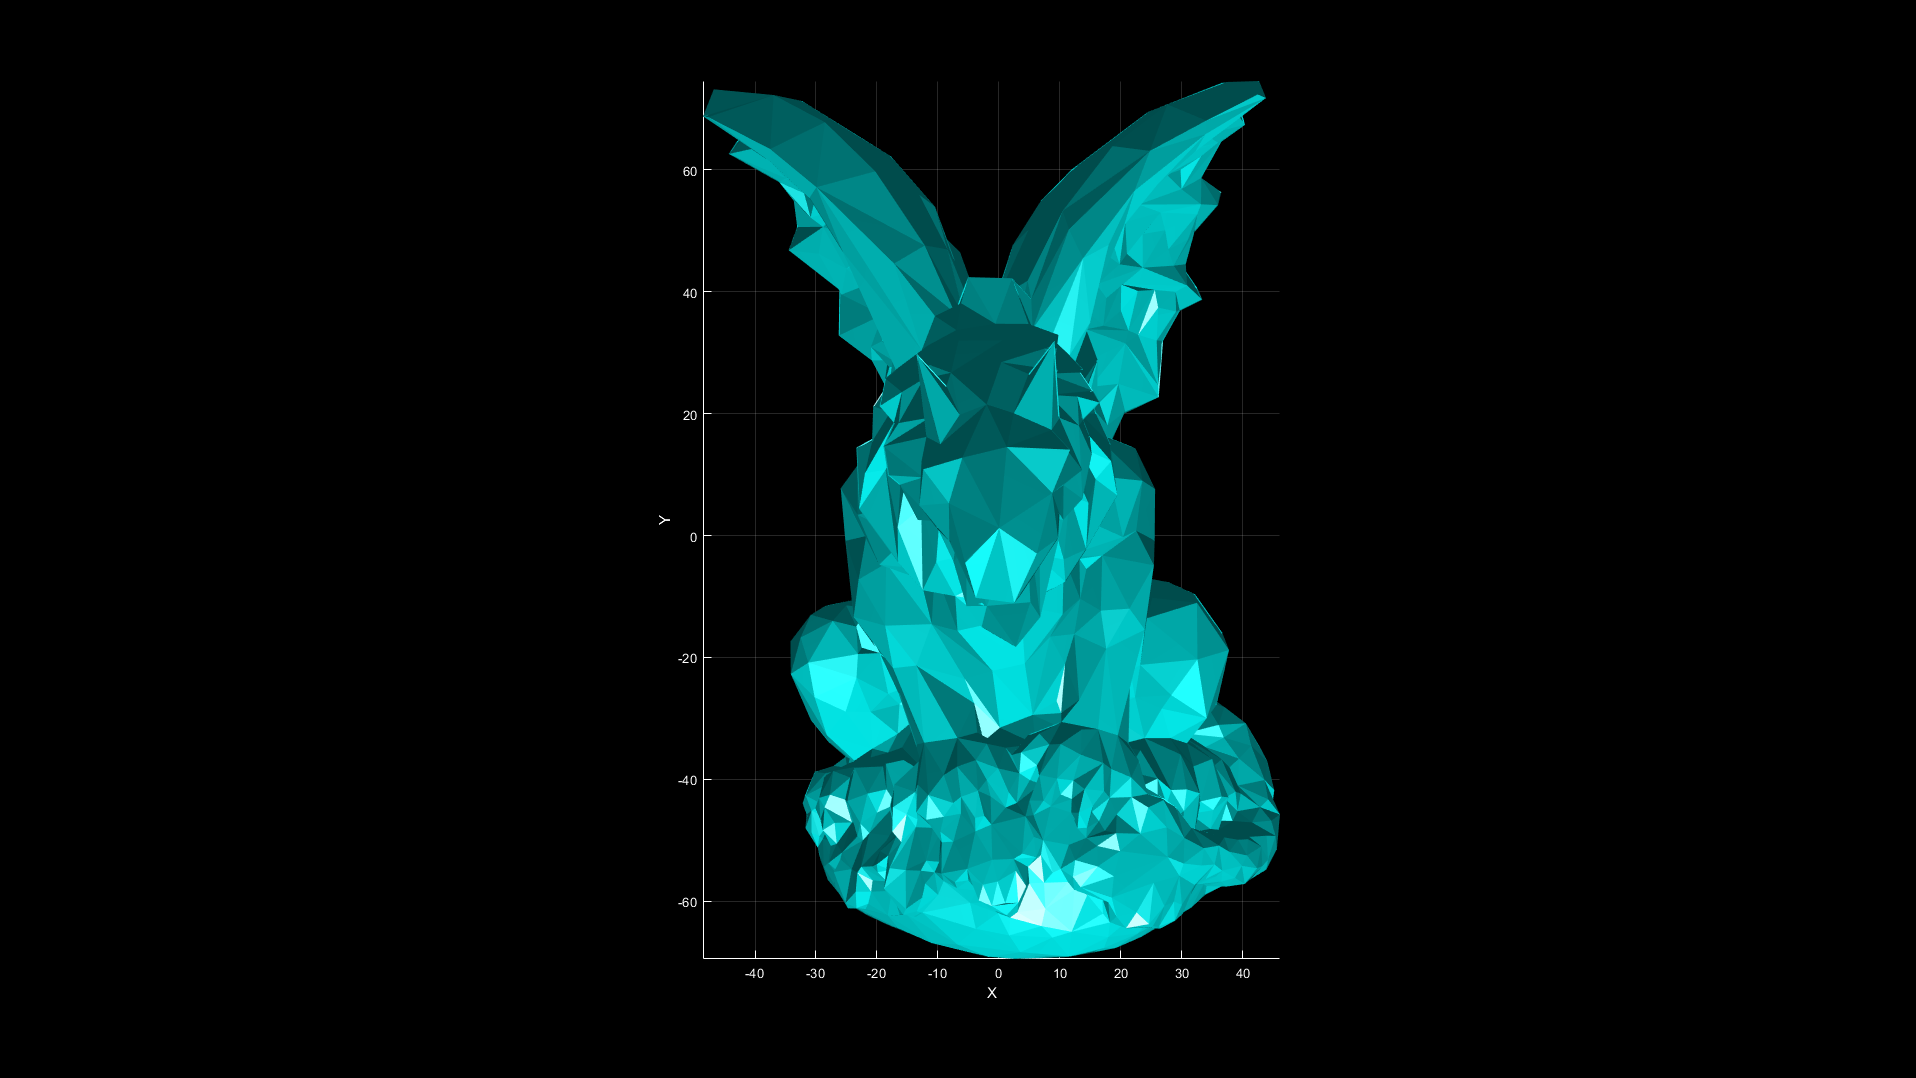

view(0,90);


N = compute_vertex_normals(V,T,2);
nb_iterations = 1;
ngb_degre = 1;
V = mesh_smooth(V,T,nb_iterations,ngb_degre);

Laplacian mesh smoothed in 5.789110e-02 seconds.



plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 7.616620e-02 seconds.


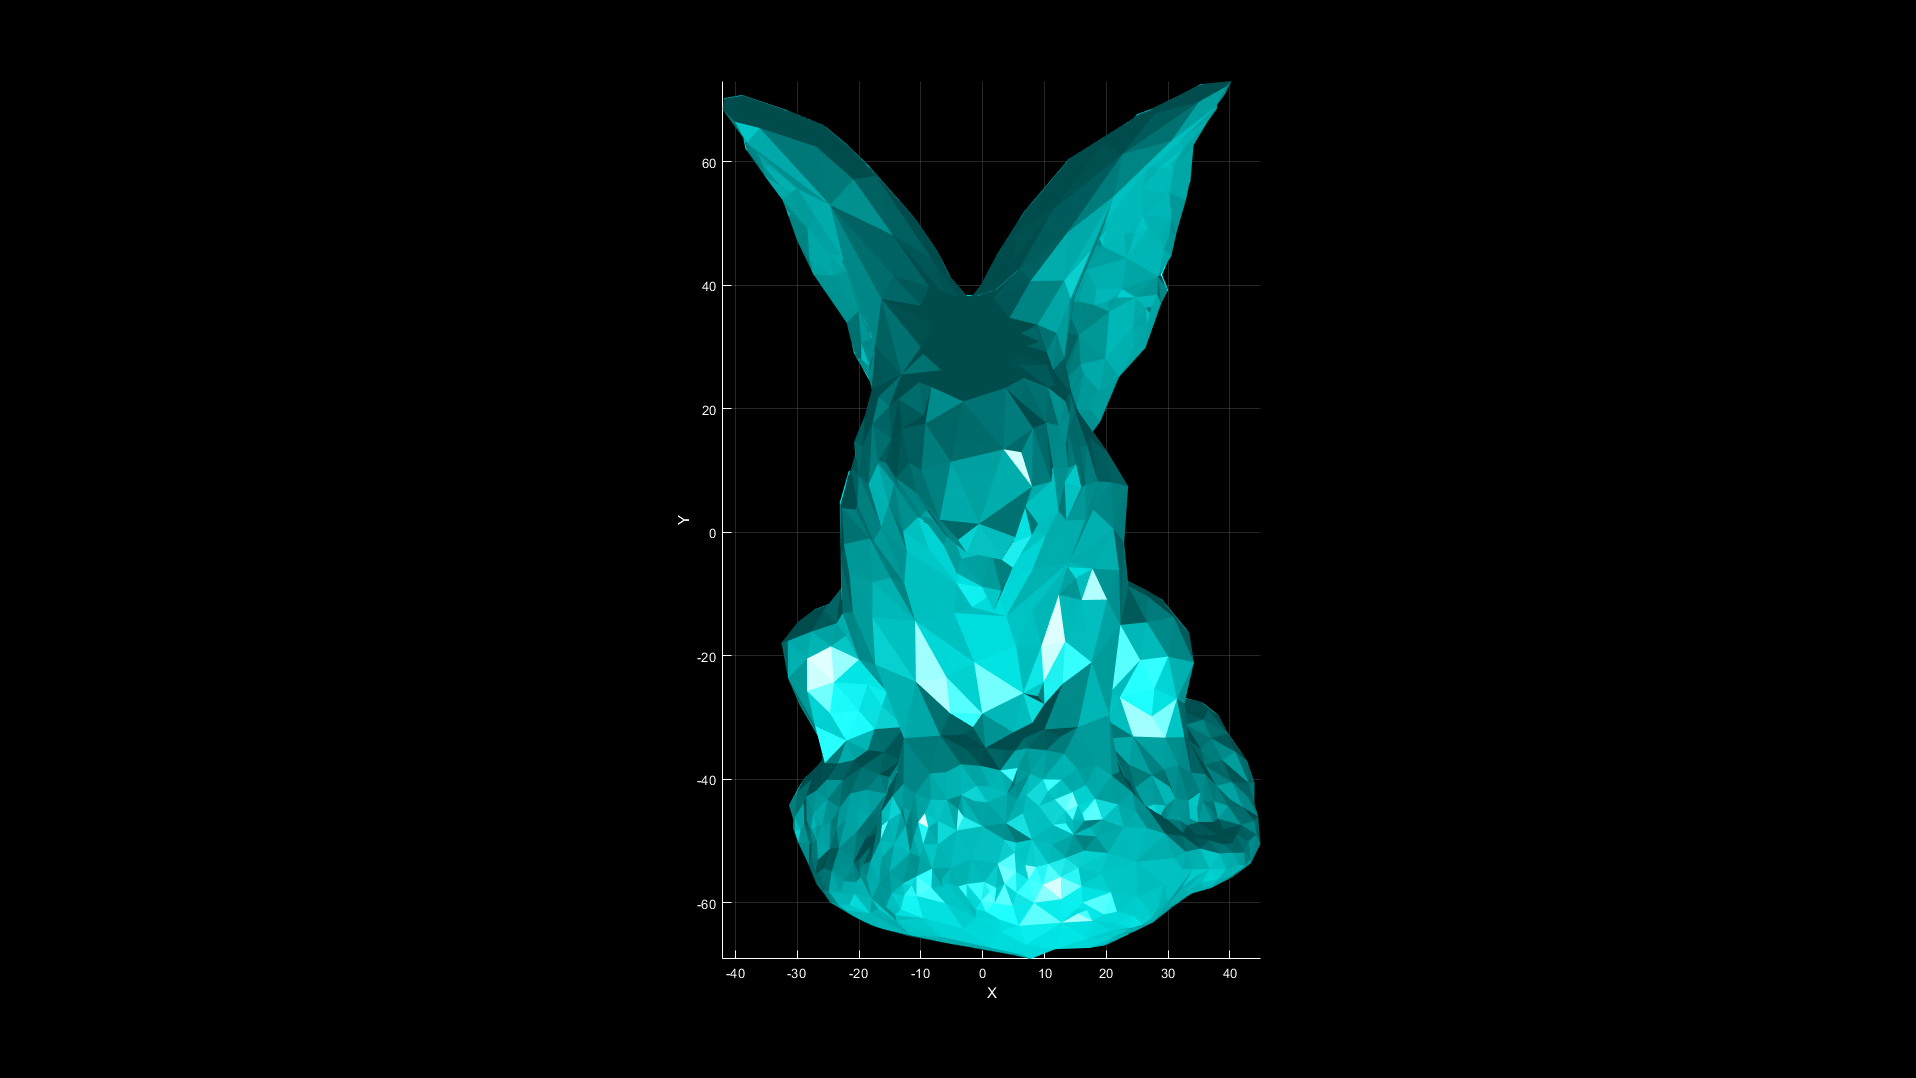

view(0,90);

### Example #9 : convex hull

load('torus_light.mat');
plot_mesh(V,T);

Mesh with 256 vertices and 480 triangles displayed in 7.616840e-02 seconds.


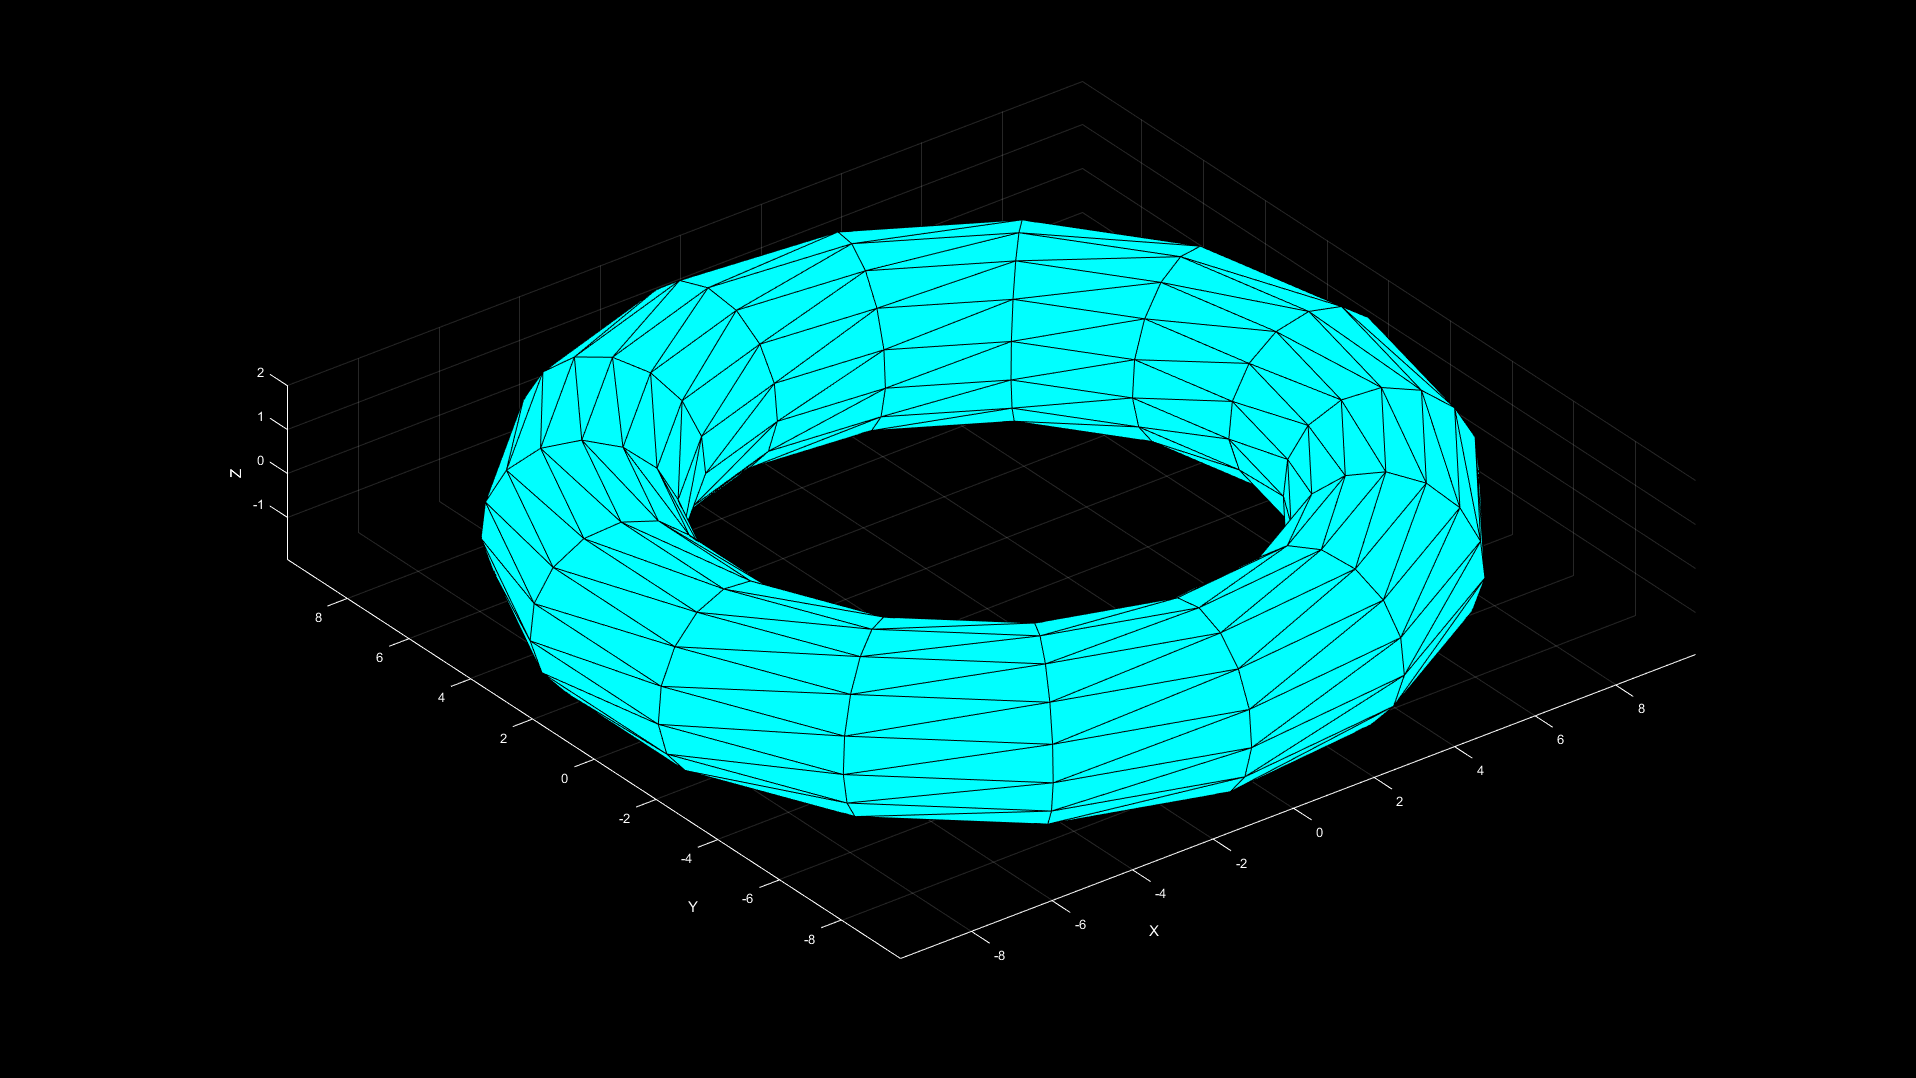

axis equal;
view(3);


[V,Qh] = quick_hull(V);

Mesh quick hull computed in 6.432616e+00s.


plot_mesh(V,Qh);

Mesh with 120 vertices and 236 triangles displayed in 6.648320e-02 seconds.


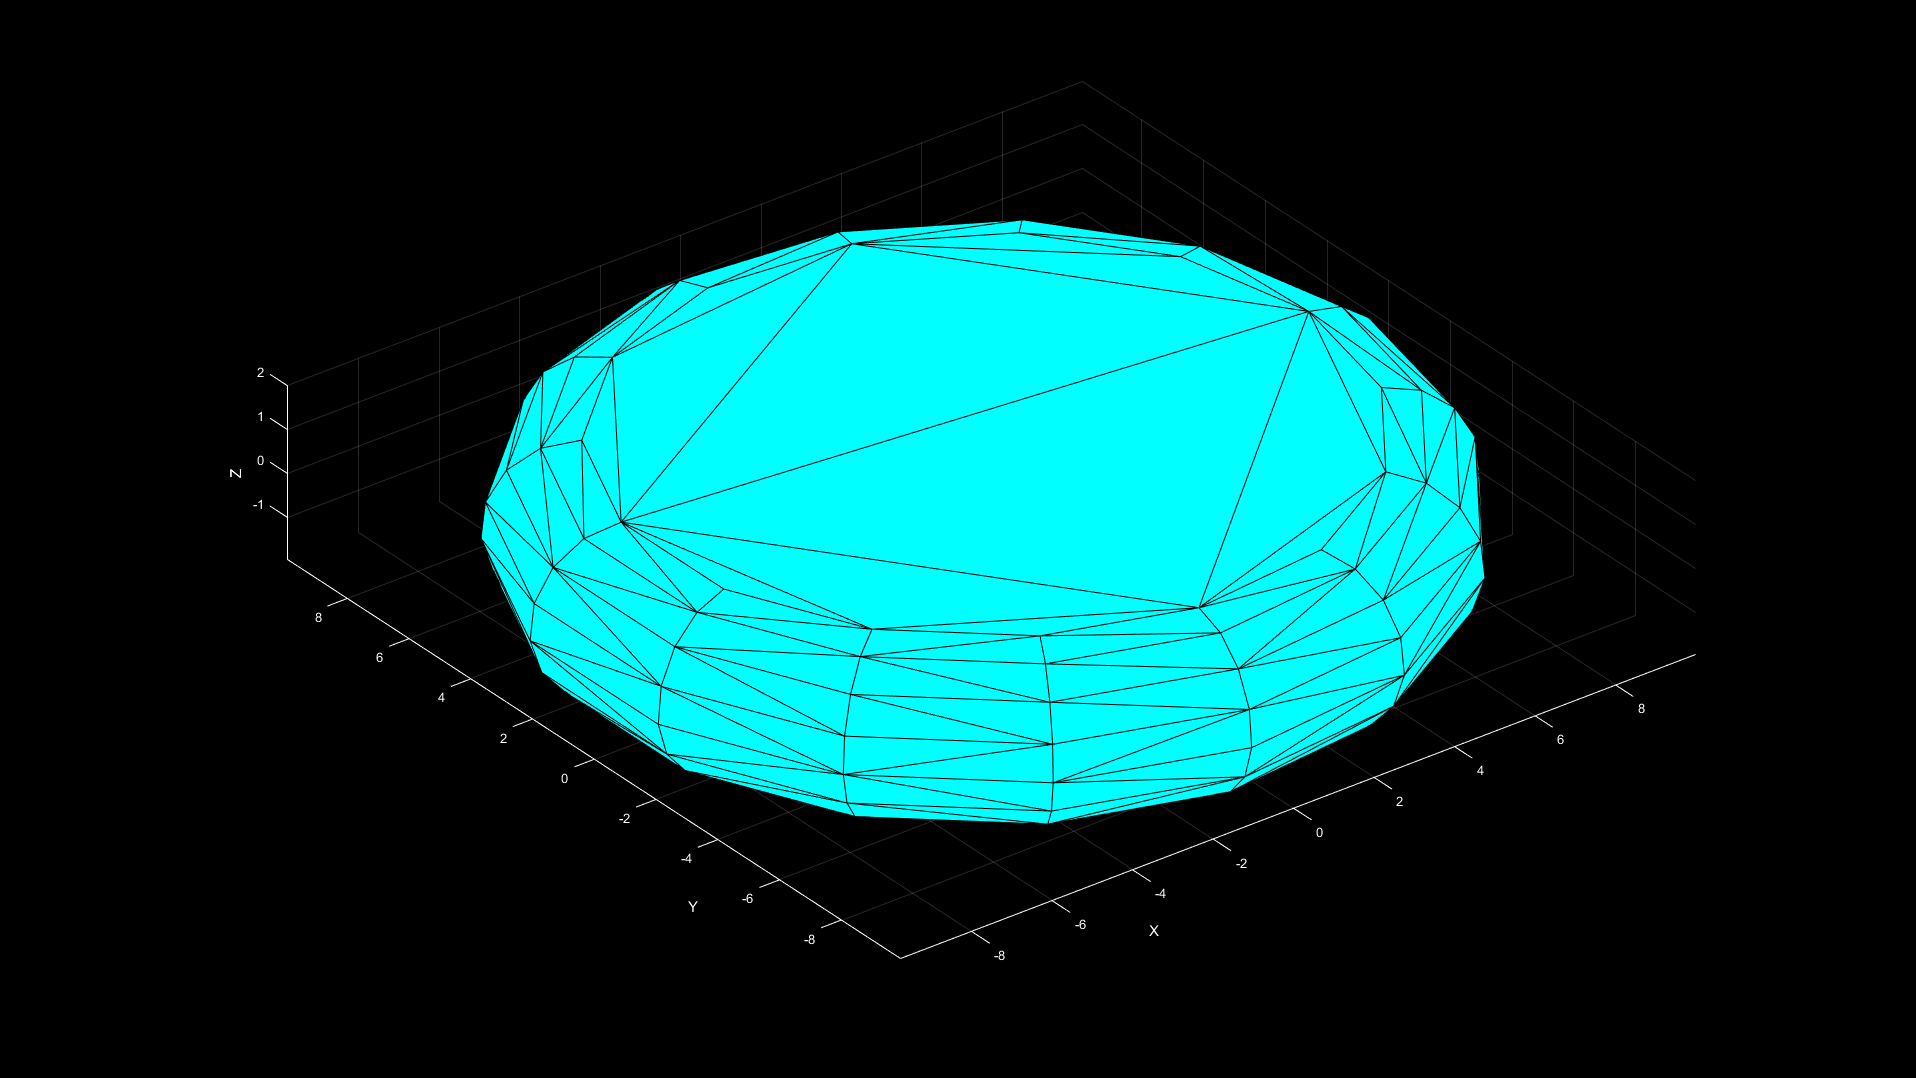

axis equal;
view(3);